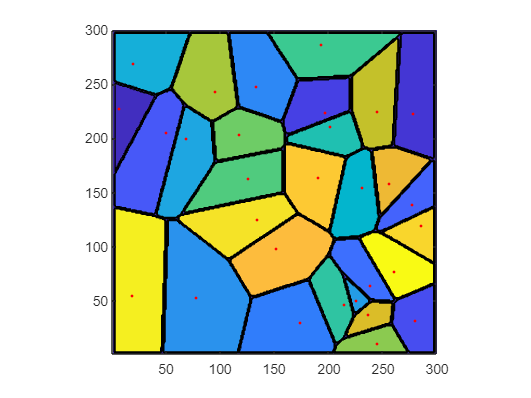

%Voronoi in 2D
areaSide = 300;
zones = 30; %Number of zones to divide the area into
borderThicknessFrac = 0.1; %as a fraction
borderThicknessAbs = 2; %as amount of distance difference in between
error = 0.01; %difference between distances to tolerate when calculating borders with method 3

area = zeros(areaSide);
centresX = randi([1 areaSide],1,zones);
centresY = randi([1 areaSide],1,zones);

for idx1 = 1:areaSide
    for idx2 = 1:areaSide
        d = distances2(centresX,centresY,idx1,idx2);
        minD = min(d);
        minDArea = find(d==minD);

        %create borders around each zone
            %Borders that are thickerthe further away they are from centres
        %diff = minD(1)*borderThicknessFrac;
        %d = d-(minD(1)+diff);
        %betweenZones = d <= 0;
            %More uniformly thick borders
        %d = d-minD(1);
        %betweenZones = d <= borderThicknessAbs;
            %borders same thickness more or less
        %d = d-(minD(1)+error*minD(1));
        %betweenZones = d <= 0;

        if sum(betweenZones) >= 2
            area(idx1,idx2) = 0;
        else
            area(idx1,idx2) = minDArea(1);
        end
    end
end

%Thickness borders taking into account neighbours, so if in middle of zone
%it won't make a border <-- Best method to get same thickness borders
%around zones. 4 and 0.985 are values that I chose through trial and error
%and I like the results they give
neighbours = diffNeighbours(area,4); %use function to round corners but 
                                     %with a smaller area around each pixel
area = area.*(neighbours > 0.985);

%Visualise zones
contourf(area,zones+1);
hold on
plot(centresY,centresX,'.r')
axis equal
hold off

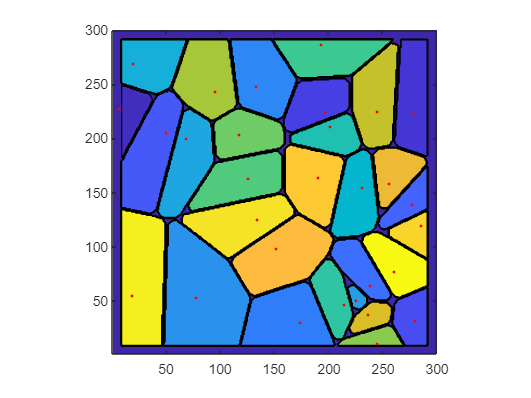


%Rounding corners (calculate how much of surrounding pixels are of same type
%so corners will have lot of different values around but centres won't)
neighbours = diffNeighbours(area);
area = area.*(neighbours > 0.5);
contourf(area,zones+1);
hold on
plot(centresY,centresX,'.r')
axis equal
hold off

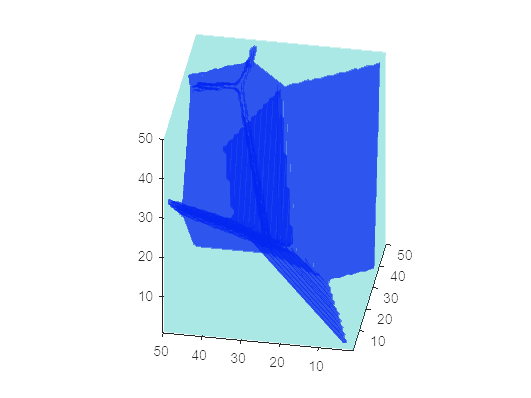

%Voronoi in 3D
areaSide = 50;
zones = 6; %Number of zones to divide the area into

area = zeros([areaSide areaSide areaSide]);
distancesCentres = zeros([areaSide areaSide areaSide]);
centresX = randi([1 areaSide],1,zones);
centresY = randi([1 areaSide],1,zones);
centresZ = randi([1 areaSide],1,zones);

for idx1 = 1:areaSide
    for idx2 = 1:areaSide
        for idx3 = 1:areaSide
            d = distances3(centresX,centresY,centresZ,idx1,idx2,idx3);
            minD = min(d);
            minDArea = find(d==minD);
    
            area(idx1,idx2,idx3) = minDArea(1);
        end
    end
end

%separate grains and edges into different arrays because method to show
%them in 3d can only have values in a matrix that can only be connected in
%one way.
areaEdges = edges3(area);
areaGrains = grains3(area.*areaEdges);

%Visualize the edges and grains. I have no idea how this code is working
%but also the visualization is crap so I should somehow change it
figure;
data = areaEdges;
patch(isocaps(data,0),...
   'FaceColor','interp','EdgeColor','none','FaceAlpha',0.2);
p1 = patch(isosurface(data,0),...
   'FaceColor','blue','EdgeColor','none','FaceAlpha',0.5);
isonormals(data,p1);
view(3); 
axis vis3d tight;


% figure;
% data = areaGrains;
% p1 = patch(isosurface(data,1),...
%    'FaceColor','red','EdgeColor','none','FaceAlpha',0.3);
% %isonormals(data,p1);
% view(3); 
% axis vis3d tight;

%% Visualise the data with ParaView
x = linspace(0,1,areaSide);
y = linspace(0,1,areaSide);
z = linspace(0,1,areaSide);
[x,y,z] = meshgrid(x,y,z);
vtkwrite('VoronoiTest.vtk','structured_grid',x,y,z,'scalars','groups',area)
vtkwrite('edges.vtk','structured_grid',x,y,z,'scalars','groups',areaEdges)

%Elongated grains 2D. Just voronoi and then contract or expand square area
%in one dimension. Problem will be that if there is a border around the
%grains it will also be elongated/contracted only in the direction of the
%deformation.


function dist = distances2(centresX,centresY,posX,posY)
    dist = zeros([1 length(centresX)]);
    for idx1 = 1:length(dist)
        dist(idx1) = sqrt((centresX(idx1)-posX)^2+(centresY(idx1)-posY)^2);
    end
end

function neighbours = diffNeighbours(area,areaSide) %function used to round the corners
                                           %of the areas
    arguments
        area
        areaSide = round(length(area)/20);
    end
    neighbours = zeros(length(area));
    halfSide = round(areaSide/2);

    for idx1 = 1:length(area)
        for idx2 = 1:length(area)
            if idx1 > halfSide && idx2 > halfSide && idx1 < length(area)-halfSide && idx2 < length(area)-halfSide && area(idx1,idx2) ~= 0
                slice = area(idx1-halfSide:idx1+halfSide,idx2-halfSide:idx2+halfSide);
                sliceEquals = slice == area(idx1,idx2);
                neighbours(idx1,idx2) = sum(sliceEquals,'all')/(areaSide^2);     
            else
                %%
                neighbours(idx1,idx2) = 0;
            end
        end
    end
end

function dist = distances3(centresX,centresY,centresZ,posX,posY,posZ)
    dist = zeros([1 length(centresX)]);
    for idx1 = 1:length(dist)
        dist(idx1) = sqrt((centresX(idx1)-posX)^2+(centresY(idx1)-posY)^2+(centresZ(idx1)-posZ)^2);
    end
end

function edges = edges3(area)
    edges = ones([length(area) length(area) length(area)]);

    for idx1 = 2:length(area)-1
        for idx2 = 2:length(area)-1
            for idx3 = 2:length(area)-1
                if area(idx1,idx2,idx3) ~= area(idx1-1,idx2,idx3) || ...
                   area(idx1,idx2,idx3) ~= area(idx1+1,idx2,idx3) || ...
                   area(idx1,idx2,idx3) ~= area(idx1,idx2-1,idx3) || ...
                   area(idx1,idx2,idx3) ~= area(idx1,idx2+1,idx3) || ...
                   area(idx1,idx2,idx3) ~= area(idx1,idx2,idx3-1) || ...
                   area(idx1,idx2,idx3) ~= area(idx1,idx2,idx3+1) 
                    edges(idx1,idx2,idx3) = 0;
                end
            end
        end
    end
end

function grains = grains3(area)
    grains = zeros([length(area) length(area) length(area)]);

    for idx1 = 3:length(area)-2
        for idx2 = 3:length(area)-2
            for idx3 = 3:length(area)-2
                if (area(idx1-1,idx2,idx3) == 0 || ...
                   area(idx1+1,idx2,idx3) == 0 || ...
                   area(idx1,idx2-1,idx3) == 0 || ...
                   area(idx1,idx2+1,idx3) == 0 || ...
                   area(idx1,idx2,idx3-1) == 0 || ...
                   area(idx1,idx2,idx3+1) == 0) && ...
                   area(idx1,idx2,idx3) ~= 0
                    grains(idx1,idx2,idx3) = area(idx1,idx2,idx3);
                elseif (area(idx1-2,idx2,idx3) == 0 || ...
                   area(idx1+2,idx2,idx3) == 0 || ...
                   area(idx1,idx2-2,idx3) == 0 || ...
                   area(idx1,idx2+2,idx3) == 0 || ...
                   area(idx1,idx2,idx3-2) == 0 || ...
                   area(idx1,idx2,idx3+2) == 0) && ...
                   area(idx1,idx2,idx3) ~= 0
                    grains(idx1,idx2,idx3) = area(idx1,idx2,idx3);
                 end
            end
        end
    end

    %Fill faces of cubic area to close the grains touching them

end